# Numerical Analysis: Assignment 2

## Problem 1 (Different Schemes to Compute Derivatives)

### Derivations:

`Using the following formula for truncation errors in derivative approximations to get the first and second derivatives:`


$$M-N_1 \left(h\right)=K_1 h^2 +K_2 h^4 +K_3 h^6 +\cdots$$


`where`


$$N_1(h)=\frac{f(x+h)-f(x-h)}{2h}$$


`This is an approximation formula in `$O\left(h^2 \right)$` for even powers of `$h$`. When `$h/2$` is used, it becomes:`


$$M-N_1 \left(h/2\right)=K_1 h^2 /4+K_2 h^4 /16+K_3 h^6 /64+\cdots$$


`Substracting the first equation from quadrable the second and dividing by 3 gives`


$$M-N_2 \left(h\right)=-K_2 h^4 /4-5K_3 h^6 /16-\cdots$$


` in `$O\left(h^4 \right)$` where`


$$N_2 \left(h\right)=N_1 \left(h/2\right)+\frac{\left\lbrack N_1 \left(h/2\right)-N_1 \left(h\right)\right\rbrack }{3}$$


`Do the same for the second approximation formula in `$O\left(h^4 \right)$`, substitute `$h$` by `$h/2$`, substract the original formula from 16 times the resultant one, then divide by 15 to get`


$$M-N_3 \left(h\right)=K_3 h^6 /64+\cdots$$


`in `$O\left(h^6 \right)$` where`


$$N_3 \left(h\right)=N_2 \left(h/2\right)+\frac{\left\lbrack N_2 \left(h/2\right)-N_2 \left(h\right)\right\rbrack }{15}$$


`Notice that we do need to compute `$N_1 \left(h/4\right)$ to be able to compute the $N_2 \left(h/2\right)$ to get $N_3 \left(h\right)$ in $O\left(h^6 \right)$.

`Same equations and line of thought would be implemented in deriving the second derivative; however, we only need to compute `$N_2 \left(h\right)$` since it is only in `$O\left(h^4 \right)$`. The only other difference is that`


$$N_1(h)=\frac{f(x_0+h)-2f(x_0)+f(x_0-h)}{h^2}$$


% Function Handle and Varaible Set
fun = @(x) sin(x);
x_0 = pi()/6;
% Preallocation
N3 = zeros(1,6);
% First-order Derivative
SN2 = zeros(1,6);
% Second-order Derivative
T3 = zeros(1,6);
% Thrid-order Derivative
L4 = zeros(1,6);
% Fourth-order Derivative
format long
for j = 1:6
% You can also use a while loop. However, be sure to add a counter for
% changing h and indexing the arrays N3, SN2, T3, and L4.
    h = 10^-j;
    % Richardson's Extrapolation:
    N1 = zeros(1,3);
    SN1 = zeros(1,2);
    N2 = zeros(1,2);
    for i = 1:3
        N1(i) = (fun(x_0+(h*2^-(i-1)))-fun(x_0-(h*2^-(i-1))))/(2*(h*2^-(i-1)));
    end
    for i = 1:2
        N2(i) = N1(i+1)+(N1(i+1)-N1(i))/3;
        SN1(i) = (fun(x_0+(h*2^-(i-1)))-2*fun(x_0)+fun(x_0-(h*2^-(i-1))))/(h*2^-(i-1))^2;
    end
    N3(j) = N2(2)+(N2(2)-N2(1))/15;
    SN2(j) = SN1(2)+(SN1(2)-SN1(1))/3;

`Third derivative using the following Taylor's expansions:`


$$f(x_0+h) = f(x_0) + f'(x_0)h+f''(x_0)\frac{h^2}{2}+ f'''(x_0)\frac{h^3}{6} + f^{(4)}(x_0)\frac{h^4}{24} + f^{(5)}(\xi_1)\frac{h^5}{120}\\
f(x_0-h) = f(x_0) - f'(x_0)h+f''(x_0)\frac{h^2}{2}- f'''(x_0)\frac{h^3}{6} + f^{(4)}(x_0)\frac{h^4}{24} - f^{(5)}(\xi_2)\frac{h^5}{120}\\
f(x_0+2h) = f(x_0) + f'(x_0)2h+f''(x_0)2h^2+ f'''(x_0)\frac{4h^3}{3} + f^{(4)}(x_0)\frac{2h^4}{3} + f^{(5)}(\xi_3)\frac{4h^5}{15}\\
f(x_0-2h) = f(x_0) - f'(x_0)2h+f''(x_0)2h^2- f'''(x_0)\frac{4h^3}{3} + f^{(4)}(x_0)\frac{2h^4}{3} - f^{(5)}(\xi_4)\frac{4h^5}{15}$$



$$\therefore f'''(x_0) = \frac{f(x_0+2h)-f(x_0-2h)-2[f(x_0+h)-f(x_0-h)]}{2h^3} + \xi h^2$$


    T3(j) = (fun(x_0+2*h)-fun(x_0-2*h)-2*fun(x_0+h)+2*fun(x_0-h))/(2*h^3);
    % Third-order derivative using Taylor expansion.

`Fourth derivative using Lagrange interpolation through `$n=5$.


$$l_i \left(x\right)=\prod_{j=0,\;i\not= j}^5 \left(\frac{x-x_j }{x_i -x_j }\right)$$



$$\begin{array}{l}
l_0 \left(x\right)=\frac{\left(x-x_1 \right)\left(x-x_2 \right)\left(x-x_3 \right)\left(x-x_4 \right)\left(x-x_5 \right)}{\left(x_0 -x_1 \right)\left(x_0 -x_2 \right)\left(x_0 -x_3 \right)\left(x_0 -x_4 \right)\left(x_0 -x_5 \right)},\;l_1 \left(x\right)=\frac{\left(x-x_0 \right)\left(x-x_2 \right)\left(x-x_3 \right)\left(x-x_4 \right)\left(x-x_5 \right)}{\left(x_1 -x_0 \right)\left(x_1 -x_2 \right)\left(x_1 -x_3 \right)\left(x_1 -x_4 \right)\left(x_1 -x_5 \right)}\\
l_2 \left(x\right)=\frac{\left(x-x_0 \right)\left(x-x_1 \right)\left(x-x_3 \right)\left(x-x_4 \right)\left(x-x_5 \right)}{\left(x_2 -x_0 \right)\left(x_2 -x_1 \right)\left(x_2 -x_3 \right)\left(x_2 -x_4 \right)\left(x_2 -x_5 \right)},\;l_3 \left(x\right)=\frac{\left(x-x_0 \right)\left(x-x_1 \right)\left(x-x_2 \right)\left(x-x_4 \right)\left(x-x_5 \right)}{\left(x_3 -x_0 \right)\left(x_3 -x_1 \right)\left(x_3 -x_2 \right)\left(x_3 -x_4 \right)\left(x_3 -x_5 \right)}\\
l_4 \left(x\right)=\frac{\left(x-x_0 \right)\left(x-x_1 \right)\left(x-x_2 \right)\left(x-x_3 \right)\left(x-x_5 \right)}{\left(x_4 -x_0 \right)\left(x_4 -x_1 \right)\left(x_4 -x_2 \right)\left(x_4 -x_3 \right)\left(x_4 -x_5 \right)},\;l_5 \left(x\right)=\frac{\left(x-x_0 \right)\left(x-x_1 \right)\left(x-x_2 \right)\left(x-x_3 \right)\left(x-x_4 \right)}{\left(x_5 -x_0 \right)\left(x_5 -x_1 \right)\left(x_5 -x_2 \right)\left(x_5 -x_3 \right)\left(x_5 -x_4 \right)}
\end{array}$$



$$\therefore l_0=\frac{-1}{5h^5}(5x-x_5-x_4-x_3-x_2-x_1)\\
\quad\! l_1=\frac{1}{h^5}(5x-x_5-x_4-x_3-x_2-x_0)\\
\quad\! l_2=\frac{-2}{h^5}(5x-x_5-x_4-x_3-x_1-x_0)\\
\quad\! l_3=\frac{2}{h^5}(5x-x_5-x_4-x_2-x_1-x_0)\\
\quad\! l_4=\frac{-1}{h^5}(5x-x_5-x_3-x_2-x_1-x_0)\\
\quad\! l_5=\frac{1}{5h^5}(5x-x_4-x_3-x_2-x_1-x_0)$$


`Then,`


$$f^{(4)}(x_0)=\frac{3f(x_0)-14f(x_0+h)+26f(x_0+2h)-24f(x_0+3h)+11f(x_0+4h)-2f(x_0+5)}{h^4}$$


    L4(j) = (3*fun(x_0)-14*fun(x_0+h)+26*fun(x_0+2*h)-24*fun(x_0+3*h)+11*fun(x_0+4*h) ...
        -2*fun(x_0+5*h))/h^4;
    % Fourth-order derivative using Lagrange interpolation. I know they are
    % basically the same thing but the approach is differnet in each one.
    fprintf("For h = %.e:\n%66s O(h\x2076) = %.13f\n%66s O(h\x2074) = %.13f\n%66s " + ...
        "O(h\x00B2) = %.13f\n%66s O(h\x00B2) = %.13f\n", h, ['First-order derivative' ...
        ' using Richardson''s extrapolation in'], N3(j), ['Second-order derivative u' ...
        'sing Richardson''s extrapolation in'], SN2(j), ['Third-order derivative usi' ...
        'ng Taylor''s expansion in'], T3(j), ['Fourth-order derivative using Lagrang' ...
        'e interpolation in'], L4(j));
end

For h = 1e-01:
        First-order derivative using Richardson's extrapolation in O(h⁶) = 0.8660254037818
       Second-order derivative using Richardson's extrapolation in O(h⁴) = -0.4999999652855
                Third-order derivative using Taylor's expansion in O(h²) = -0.8638625041217
           Fourth-order derivative using Lagrange interpolation in O(h²) = 0.5182009667970
For h = 1e-02:
        First-order derivative using Richardson's extrapolation in O(h⁶) = 0.8660254037844
       Second-order derivative using Richardson's extrapolation in O(h⁴) = -0.4999999999966
                Third-order derivative using Taylor's expansion in O(h²) = -0.8660037533748
           Fourth-order derivative using Lagrange interpolation in O(h²) = 0.5001459468801
For h = 1e-03:
        First-order derivative using Richardson's extrapolation in O(h⁶) = 0.8660254037841
       Second-order derivative using Richardson's extrapolation in O(h⁴) = -0.4999999997738
                Third-order derivative u

### Error Analysis:

`For the third-derivative, the collective error `$\left(\sigma \right)$` due to the round-off and numerical errors can be about`


$$\sigma (f''') \leq \frac{2\varepsilon}{h^2}+\frac{21h^2}{40}$$


`where `$\varepsilon$` is machine epsilon.`

fprintf('Machine Epsilon = %.2e', eps)

Machine Epsilon = 2.22e-16


$$\frac{\mathrm{d}}{\mathrm{d}h}\sigma_{\max } =-\frac{4\varepsilon }{{h_{\min } }^3 }+\frac{21h_{\min } }{20}=0$$



$$h_{\min } =\sqrt[4]{\frac{80\epsilon }{21}}$$


fprintf(['Minimum step value for third derivatives is approximately of magnitude %.e' ...
    '.\nHence, the inaccuracy in the last two values for the third derivative.'], (80 ...
    *eps/21)^(1/4))

Minimum step value for third derivatives is approximately of magnitude 2e-04.
Hence, the inaccuracy in the last two values for the third derivative.

`Using the same technique for the fourth derivative formula,`


$$\sigma (f^{(4)}) \leq \frac{80\varepsilon}{h^4}+\frac{729h^2}{720}$$



$$\frac{\mathrm{d}}{\mathrm{d}h}\sigma_{\max } =-\frac{320\varepsilon }{{h_{\min } }^5 }+\frac{81h_{\min } }{40}=0$$



$$h_{\min } =\sqrt[6]{\frac{12800\epsilon }{81}}$$


fprintf(['Minimum step value for fourth derivatives is approximately of magnitude %.' ...
    'e.\nHence, the inaccuracy in the last three values for the third derivative.'],  ...
    (12800*eps/81)^(1/6))

Minimum step value for fourth derivatives is approximately of magnitude 6e-03.
Hence, the inaccuracy in the last three values for the third derivative.

`which is valid since the value for the fouth derivative when `$h=1\times {10}^{-3}$` goes under the true value unlike the first two approximations. Thus, indicating the perturbation of the true value.`

`We can also simplify this analysis by using the formula for higher-order Lagrange interpolations along with its error estimate:`


$$f\left(x\right)=\sum_{k=0}^n f\left(x_k \right)L_{n,k} \left(x\right)+\underbrace{\frac{f^{\left(n+1\right)} \left(\xi \left(x\right)\right)}{\left(n+1\right)!}\prod_{k=0}^n \left(x-x_k \right)}$$


`The underbraced term is the numerical error, giving the minimum steps to be`


$$\sigma (f''') \leq \frac{N\varepsilon}{h^2}+\frac{Mh^2}{4!},\quad h_{min}\propto \sqrt[4]{4!}$$



$$\sigma (f^{(4)}) \leq \frac{N\varepsilon}{h^4}+\frac{Mh^2}{5!},\quad h_{min}\propto \sqrt[6]{2\times5!}$$


fprintf(['Minimum step value for Third derivatives is approximately of magnitude %.' ...
    'e.\nMinimum step value for fourth derivatives is approximately of magnitude %.' ...
    'e.'], (fact(4)*eps)^(1/4), (2*fact(5)*eps)^(1/6))

Minimum step value for Third derivatives is approximately of magnitude 3e-04.
Minimum step value for fourth derivatives is approximately of magnitude 6e-03.

`which agrees with the prior findings. Moreover, one can overcome this rounding error dominance over the numerical error through adding more terms to eliminate the terms containing smaller powers of h which what exactly happens in Richardson’s extrapolation.`

## Problem 2 (5-Point Formula and its Error Bound)

`Five-Point Midpoint Formula:`


$$f^{\prime } \left(x_0 \right)=\frac{f\left(x_0 -2h\right)-8f\left(x_0 -h\right)+8f\left(x_0 +h\right)-f\left(x_0 +2h\right)}{12h}+\frac{h^4 }{30}f^{\left(5\right)} \left(\xi \right)$$


`where `$\xi \in \left\lbrack x_0 -2h,\;x_0 +2h\right\rbrack$

`Five-Point Endpoint Formula:`


$$f^{\prime } \left(x_0 \right)=\frac{-25f\left(x_0 \right)+48f\left(x_0 +h\right)-36f\left(x_0 +2h\right)+16f\left(x_0 +3h\right)-3f\left(x_0 +4h\right)}{12h}+\frac{h^4 }{5}f^{\left(5\right)} \left(\xi \right)$$


`where `$\xi \in \left\lbrack x_0 ,\;x_0 +4h\right\rbrack$

`Hence, using the midpoint formula for the third and fourth points only while using the endpoint one for the first, second, fifth, and sixth points.`

x_j = [1.05, 1.10, 1.15, 1.20, 1.25, 1.30];
y_j = [-1.709847, -1.373823, -1.119214, -0.9160143, -0.7470223, -0.6015966];

r = randperm(6,2);
h = abs(x_j(r(1))-x_j(r(2)));
% This is not necessary whatsoever, for it is clear h = 0.05.

FOD = zeros(1,6);
% I think it's good practice to store these results in the form of an array.
for j = 1:6
    if j == 1 || j == 2
        FOD(j) = (-25*y_j(j)+48*y_j(j+1)-36*y_j(j+2)+16*y_j(j+3)-3*y_j(j+4))/(12*h);
        lo_b = x_j(j);
        up_b = lo_b+4*h;
    elseif  j == 3 || j == 4
        FOD(j) = (y_j(j-2)-8*y_j(j-1)+8*y_j(j+1)-y_j(j+2))/(12*h);
        lo_b = x_j(j)-2*h;
        up_b = lo_b+4*h;
    else
        FOD(j) = (-25*y_j(j)+48*y_j(j-1)-36*y_j(j-2)+16*y_j(j-3)-3*y_j(j-4))/(12*-h);
        lo_b = x_j(j);
        up_b = lo_b-4*h;
    end
    fprintf(['First-order derivative approximation for x\x2080 = %.2f in O(h\x2074) ' ...
        '= %9.6f with \x03BE lying between %.2f and %.2f\n'], x_j(j), FOD(j), ...
        min(lo_b,up_b), max(up_b,lo_b))
end

First-order derivative approximation for x₀ = 1.05 in O(h⁴) =  7.798688 with ξ lying between 1.05 and 1.25
First-order derivative approximation for x₀ = 1.10 in O(h⁴) =  5.753751 with ξ lying between 1.10 and 1.30
First-order derivative approximation for x₀ = 1.15 in O(h⁴) =  4.499408 with ξ lying between 1.05 and 1.25
First-order derivative approximation for x₀ = 1.20 in O(h⁴) =  3.675512 with ξ lying between 1.10 and 1.30
First-order derivative approximation for x₀ = 1.25 in O(h⁴) =  3.088420 with ξ lying between 1.05 and 1.25
First-order derivative approximation for x₀ = 1.30 in O(h⁴) =  2.710993 with ξ lying between 1.10 and 1.30


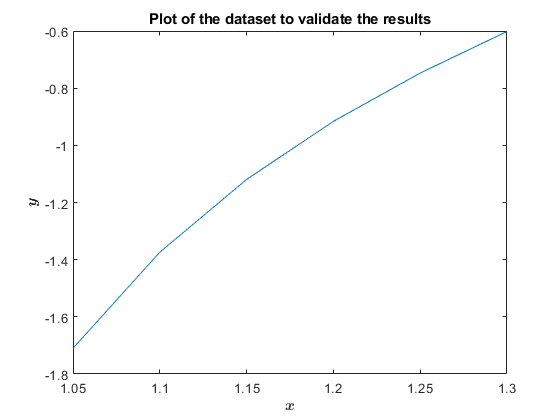


% To validate the results, we can make sure the slope is always positive
% and getting smaller and smaller.
figure(1)
plot(x_j.',y_j.','-')
xticks(x_j(1):h:x_j(length(x_j)));
title('Plot of the dataset to validate the results')
xlabel('{\boldmath$x$}','Interpreter','latex');
ylabel('{\boldmath$y$}','Interpreter','latex');

`Which shows the slope is, indeed, always positive and decreasing.`

## Problem 3 (Lagrange Interpolation)


$$l_i \left(x\right)=\prod_{j=0,\;i\not= j}^n \left(\frac{x-x_j }{x_i -x_j }\right)$$


`where `$n=20$` in this case. Thus,`


$$P_{20} \left(x\right)=\sum_{i=0}^{20} l_i \left(x\right)\cdot y_i$$


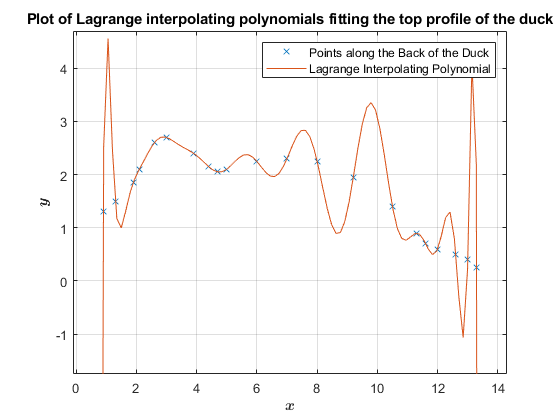

x_i = [0.9 1.3 1.9 2.1 2.6 3.0 3.9 4.4 4.7 5.0 6.0 7.0 8.0 9.2 10.5 11.3 ...
 11.6 12.0 12.6 13.0 13.3];
y_i = [1.3 1.5 1.85 2.1 2.6 2.7 2.4 2.15 2.05 2.1 2.25 2.3 2.25 1.95 1.4 ...
 0.9 0.7 0.6 0.5 0.4 0.25];
x = linspace(min(x_i)-1, max(x_i)+1);
% This is a vector of points where the interpolation will be evaluated. The
% use of max and min throughout the code is just for aesthetics and generality.
l = ones(length(x_i), length(x));
y = zeros(1,100);
% As the default argument for linspace creates 100 data points.
for i = 1:length(x_i)
    for j = 1:length(x_i)
        if i ~= j
            l(i,:) = l(i,:).*(x-x_i(j))/(x_i(i)-x_i(j));
        end
    end
    y = y + y_i(i)*l(i,:);
    % This will produce a vector of interpolation points for all x after the loop ends.
    % This acts as a Fourier series of sorts. Adjusting y for each x at each iteration.
end

figure(2)
plot(x_i.',y_i.','x', 'DisplayName', 'Points along the Back of the Duck')
hold on
plot(x, y, '-', 'DisplayName', 'Lagrange Interpolating Polynomial')
hold off

grid
legend
title('Plot of Lagrange interpolating polynomials fitting the top profile of the duck')
xlim([min(x_i)-1 max(x_i)+1])
ylim([min(y_i)-2 max(y_i)+2])
xlabel('{\boldmath$x$}','Interpreter','latex');
ylabel('{\boldmath$y$}','Interpreter','latex');

`Now, I'll overlay the plot on the duck figure.`

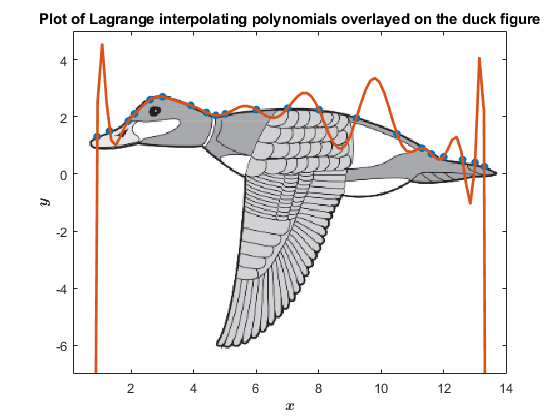

Imm = imread('FILEPATH\Duck (Inverted).png');

figure (3)
image(rot90(Imm,2), 'XData', [0.15 14], 'YData', [-6.3 2.9])
hold on
plot(x_i.', y_i.', '.', 'MarkerSize', 20)
plot(x, y, '-', 'LineWidth', 2)
hold off

grid off
title('Plot of Lagrange interpolating polynomials overlayed on the duck figure')
set(gca,'YDir','normal')
ylim([-7 5])
xlabel('{\boldmath$x$}','Interpreter','latex');
ylabel('{\boldmath$y$}','Interpreter','latex');

function f = fact(num)
% Factorial of number "num".
%
%   Input: num, any number belonging to N
%   Output: fact, the factorial of said number
%
%See also factorial.

if num ~= 0
    f = 1;
    for i = 1:num
        f = f*i;
    end
else
    f = 1;
end
end